% ใช้โมเดลจาก SurrogateOptimizationModule_FileExchange
% https://www.mathworks.com/matlabcentral/fileexchange/38530-surrogate-model-optimization-toolbox

% เคลียร์ข้อมูลก่อนรันโค้ดใหม่
clear all, close all, clc

% % เพิ่มเส้นทางของโฟลเดอร์ '0.Surrogate model & Optimization'
% % และโฟลเดอร์ย่อยทั้งหมดที่อยู่ภายในโฟลเดอร์นี้
% folder_path = '0.Surrogate model & Optimization';
% addpath(genpath(folder_path));

% โหลดข้อมูลจาก .m file
load("kmeans_sampling_training.mat")

% สร้าง struct Data สำหรับเก็บตัวแปรของของ Training set
% โดยข้อมูลตัวแปรต้นและตัวแปรตามจะถูกเก็บไว้ใน Data 
% X-triain : S ;  Y-train : Ymed ; ขนาดของตัวแปร X : dim
% กำหนดตัวแปร Y1 % Electric Power 
Y1_ElectricalPower = clean_data(:,25);
Data.ElectricalPower.S = X_sampling_training;
Data.ElectricalPower.Ymed = Y1_sampling_training;
Data.ElectricalPower.dim = size(clean_data(:,1:24),2); % จำนวนตัวแปรต้น 

% กำหนดตัวแปร Y2 % Heat Rejection
Y2_HeatRejection = clean_data(:,26);
Data.HeatRejection.S = X_sampling_training;
Data.HeatRejection.Ymed = Y2_sampling_training;
Data.HeatRejection.dim = size(clean_data(:,1:24),2); % จำนวนตัวแปรต้น  
Data.dim = size(clean_data(:,1:24),2);

% [lambda,gamma,dmodel,mmodel,beta, w_m] = FitSurrogateModel(Data.ElectricalPower, 'KRIGexp2')

% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'KRIGcub0', 'KRIGcub1', 'KRIGcub2', 'KRIGexp0', 'KRIGexp1', 'KRIGexp2',...
    'KRIGgexp0', 'KRIGgexp1', 'KRIGgexp2', 'KRIGgauss0', 'KRIGgauss1', 'KRIGgauss2',...
    'KRIGlin0', 'KRIGlin1', 'KRIGlin2', 'KRIGspline0', 'KRIGspline1', 'KRIGspline2',...
    'KRIGsphere0', 'KRIGsphere1', 'KRIGsphere2'};

% สร้าง struct สำหรับเก็บผลลัพธ์
results = struct();

% วนลูปเพื่อรันแต่ละโมเดลและบันทึกผลลัพธ์
for i = 1:length(models)
    % สร้าง struct เพื่อเก็บตัวแปรของโมเดล
    model = struct();
    model.Surrogate = models{i};
    
    % รัน FitSurrogateModel
    [model.ElectricalPower.lambda, model.ElectricalPower.gamma, model.ElectricalPower.dmodel, model.ElectricalPower.mmodel, model.ElectricalPower.beta, model.ElectricalPower.w_m] = FitSurrogateModel(Data.ElectricalPower, model.Surrogate);
    [model.HeatRejection.lambda, model.HeatRejection.gamma, model.HeatRejection.dmodel, model.HeatRejection.mmodel, model.HeatRejection.beta, model.HeatRejection.w_m] = FitSurrogateModel(Data.HeatRejection, model.Surrogate);
    
    % รัน PredictFunctionValues
    model.ElectricalPower_Predicted = PredictFunctionValues(Data.ElectricalPower, models{i}, X_test, model.ElectricalPower.lambda, model.ElectricalPower.gamma,...
        model.ElectricalPower.dmodel, model.ElectricalPower.beta, model.ElectricalPower.mmodel, model.ElectricalPower.w_m);
    model.HeatRejection_Predicted = PredictFunctionValues(Data.HeatRejection, models{i}, X_test, model.HeatRejection.lambda, model.HeatRejection.gamma,...
        model.HeatRejection.dmodel, model.HeatRejection.beta, model.HeatRejection.mmodel, model.HeatRejection.w_m);
    
    % คำนวน %rmse
    model.ElectricalPower_PRMSE = ((sqrt(mean((Y1_ElectricPower_test-model.ElectricalPower_Predicted).^2)))/(max(Y1_ElectricalPower)-min(Y1_ElectricalPower)))*100;
    model.HeatRejection_PRMSE = ((sqrt(mean((Y2_HeatRejection_test-model.HeatRejection_Predicted).^2)))/(max(Y2_HeatRejection)-min(Y2_HeatRejection)))*100;
     
    % เก็บผลลัพธ์ใน struct results
    results.(models{i}) = model;
end

% แสดงผลลัพธ์
fprintf('Heat Rejection PRMSE:\n');
for i = 1:length(models)
    fprintf('%s: %f\n', models{i}, results.(models{i}).HeatRejection_PRMSE);
end

fprintf('--------------------------------')
% แสดงผลลัพธ์
fprintf('Electrical Power PRMSE:\n');
for i = 1:length(models)
    fprintf('%s: %f\n', models{i}, results.(models{i}).ElectricalPower_PRMSE);
end

% % สร้าง cell array เพื่อเก็บชื่อโมเดล
% % สร้าง cell array เพื่อเก็บชื่อโมเดล
% models = {'KRIGcub0', 'KRIGcub1', 'KRIGcub2', 'KRIGexp0', 'KRIGexp1', 'KRIGexp2',...
%     'KRIGgexp0', 'KRIGgexp1', 'KRIGgexp2', 'KRIGgauss0', 'KRIGgauss1', 'KRIGgauss2',...
%     'KRIGlin0', 'KRIGlin1', 'KRIGlin2', 'KRIGspline0', 'KRIGspline1', 'KRIGspline2',...
%     'KRIGsphere0', 'KRIGsphere1', 'KRIGsphere2'};
% names = {'Actual','KRIGcub0', 'KRIGcub1', 'KRIGcub2', 'KRIGexp0', 'KRIGexp1', 'KRIGexp2',...
%     'KRIGgexp0', 'KRIGgexp1', 'KRIGgexp2', 'KRIGgauss0', 'KRIGgauss1', 'KRIGgauss2',...
%     'KRIGlin0', 'KRIGlin1', 'KRIGlin2', 'KRIGspline0', 'KRIGspline1', 'KRIGspline2',...
%     'KRIGsphere0', 'KRIGsphere1', 'KRIGsphere2'};
% % สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
% colors = {'#77AC30', '#0072BD', '#4DBEEE'};
% markers = {'o', 'x', '^'};
% 
% % พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
% figure;
% hold on;
% % พล็อตค่าจริง
% plot(Y1_ElectricPower_test, Y1_ElectricPower_test, 'k-',LineWidth = 3);
% for i = 1:length(models)
%     model = results.(models{i});
%     plot(Y1_ElectricPower_test, model.ElectricalPower_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
% end
% ylim([min(Y1_ElectricPower_test), max(Y1_ElectricPower_test)]);
% 
% % ตกแต่งกราฟ
% title(' Electric Power Actual vs MARS Predicted');
% 
% legend(names, 'Location', 'best');
% hold off;

% สร้าง cell array เพื่อเก็บชื่อโมเดล
% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'KRIGcub1','KRIGexp1','KRIGgexp1', 'KRIGgauss1',...
    'KRIGlin1','KRIGspline1','KRIGsphere1'};
names = {'Actual','KRIGcub1','KRIGexp1','KRIGgexp1', 'KRIGgauss1',...
    'KRIGlin1','KRIGspline1','KRIGsphere1'};
% สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
% colors = {'#D95319', '#0072BD', '#A2142F'};
markers = {'o', 'x', '^','*','+','s','>'};

% พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
figure;
hold on;
% พล็อตค่าจริง
plot(Y1_ElectricPower_test, Y1_ElectricPower_test, 'k-',LineWidth = 3);
for i = 1:length(models)
    model = results.(models{i});
    plot(Y1_ElectricPower_test, model.ElectricalPower_Predicted, markers{i},'MarkerSize',3);
end
ylim([min(Y1_ElectricPower_test), max(Y1_ElectricPower_test)]);

% ตกแต่งกราฟ
title(' Electric Power Actual vs Kriging cubic Predicted');

legend(names, 'Location', 'best');
hold off;

% สร้าง cell array เพื่อเก็บชื่อโมเดล
% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'KRIGcub0', 'KRIGcub1', 'KRIGcub2'};
names = {'Actual','KRIGcub0', 'KRIGcub1', 'KRIGcub2'};
% สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
colors = {'#D95319', '#0072BD', '#A2142F'};
markers = {'o', 'x', '^'};

% พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
figure;
hold on;
% พล็อตค่าจริง
plot(Y1_ElectricPower_test, Y1_ElectricPower_test, 'k-',LineWidth = 3);
for i = 1:length(models)
    model = results.(models{i});
    plot(Y1_ElectricPower_test, model.ElectricalPower_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
end
ylim([min(Y1_ElectricPower_test), max(Y1_ElectricPower_test)]);

% ตกแต่งกราฟ
title(' Electric Power Actual vs Kriging cubic Predicted');

legend(names, 'Location', 'best');
hold off;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% สร้าง cell array เพื่อเก็บชื่อโมเดล
% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'KRIGexp0', 'KRIGexp1', 'KRIGexp2'};
names = {'Actual','KRIGexp0', 'KRIGexp1', 'KRIGexp2'};
% สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
colors = {'#0072BD', '#D95319', '#EDB120'};
markers = {'o', 'x', '^'};

% พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
figure;
hold on;
% พล็อตค่าจริง
plot(Y1_ElectricPower_test, Y1_ElectricPower_test, 'k-',LineWidth = 3);
for i = 1:length(models)
    model = results.(models{i});
    plot(Y1_ElectricPower_test, model.ElectricalPower_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
end
ylim([min(Y1_ElectricPower_test), max(Y1_ElectricPower_test)]);

% ตกแต่งกราฟ
title(' Electric Power Actual vs Kriging exponential Predicted');

legend(names, 'Location', 'best');
hold off;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% สร้าง cell array เพื่อเก็บชื่อโมเดล
% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'KRIGgexp0', 'KRIGgexp1', 'KRIGgexp2'};
names = {'Actual','KRIGgexp0', 'KRIGgexp1', 'KRIGgexp2'};
% สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
colors = {'#7E2F8E', 'b', '#00FFFF'};
markers = {'o', 'x', '^'};

% พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
figure;
hold on;
% พล็อตค่าจริง
plot(Y1_ElectricPower_test, Y1_ElectricPower_test, 'k-',LineWidth = 3);
for i = 1:length(models)
    model = results.(models{i});
    plot(Y1_ElectricPower_test, model.ElectricalPower_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
end
ylim([min(Y1_ElectricPower_test), max(Y1_ElectricPower_test)]);

% ตกแต่งกราฟ
title(' Electric Power Actual vs Kriging generalized exponential Predicted');

legend(names, 'Location', 'best');
hold off;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% สร้าง cell array เพื่อเก็บชื่อโมเดล
% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'KRIGgauss0', 'KRIGgauss1', 'KRIGgauss2'};
names = {'Actual','KRIGgauss0', 'KRIGgauss1', 'KRIGgauss2'};
% สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
colors = {'#A2142F', '#FF00FF', '#00FF00'};
markers = {'o', 'x', '^'};

% พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
figure;
hold on;
% พล็อตค่าจริง
plot(Y1_ElectricPower_test, Y1_ElectricPower_test, 'k-',LineWidth = 3);
for i = 1:length(models)
    model = results.(models{i});
    plot(Y1_ElectricPower_test, model.ElectricalPower_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
end
ylim([min(Y1_ElectricPower_test), max(Y1_ElectricPower_test)]);

% ตกแต่งกราฟ
title(' Electric Power Actual vs Kriging gaussian Predicted');

legend(names, 'Location', 'best');
hold off;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% สร้าง cell array เพื่อเก็บชื่อโมเดล
% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'KRIGlin0', 'KRIGlin1', 'KRIGlin2'};
names = {'Actual','KRIGlin0', 'KRIGlin1', 'KRIGlin2'};
% สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
colors = {'#FF0000', '#EDB120', '#000000'};
markers = {'o', 'x', '^'};

% พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
figure;
hold on;
% พล็อตค่าจริง
plot(Y1_ElectricPower_test, Y1_ElectricPower_test, 'k-',LineWidth = 3);
for i = 1:length(models)
    model = results.(models{i});
    plot(Y1_ElectricPower_test, model.ElectricalPower_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
end
ylim([min(Y1_ElectricPower_test), max(Y1_ElectricPower_test)]);

% ตกแต่งกราฟ
title(' Electric Power Actual vs Kriging linear Predicted');

legend(names, 'Location', 'best');
hold off;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% สร้าง cell array เพื่อเก็บชื่อโมเดล
% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'KRIGspline0', 'KRIGspline1', 'KRIGspline2'};
names = {'Actual','KRIGspline0', 'KRIGspline1', 'KRIGspline2'};
% สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
colors = {'#0000FF', '#00FFFF', '#D95319'};
markers = {'o', 'x', '^'};

% พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
figure;
hold on;
% พล็อตค่าจริง
plot(Y1_ElectricPower_test, Y1_ElectricPower_test, 'k-',LineWidth = 3);
for i = 1:length(models)
    model = results.(models{i});
    plot(Y1_ElectricPower_test, model.ElectricalPower_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
end
ylim([min(Y1_ElectricPower_test), max(Y1_ElectricPower_test)]);

% ตกแต่งกราฟ
title(' Electric Power Actual vs Kriging spline Predicted');

legend(names, 'Location', 'best');
hold off;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% สร้าง cell array เพื่อเก็บชื่อโมเดล
% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'KRIGsphere0', 'KRIGsphere1', 'KRIGsphere2'};
names = {'Actual','KRIGsphere0', 'KRIGsphere1', 'KRIGsphere2'};
% สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
colors = {'#00FF00', '#0072BD', '#A2142F'};
markers = {'o', 'x', '^'};

% พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
figure;
hold on;
% พล็อตค่าจริง
plot(Y1_ElectricPower_test, Y1_ElectricPower_test, 'k-',LineWidth = 3);
for i = 1:length(models)
    model = results.(models{i});
    plot(Y1_ElectricPower_test, model.ElectricalPower_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
end
ylim([min(Y1_ElectricPower_test), max(Y1_ElectricPower_test)]);

% ตกแต่งกราฟ
title(' Electric Power Actual vs Kriging spherical Predicted');

legend(names, 'Location', 'best');
hold off;

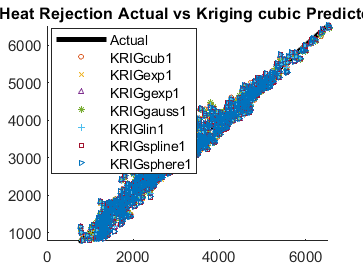

% สร้าง cell array เพื่อเก็บชื่อโมเดล
% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'KRIGcub1','KRIGexp1','KRIGgexp1', 'KRIGgauss1',...
    'KRIGlin1','KRIGspline1','KRIGsphere1'};
names = {'Actual','KRIGcub1','KRIGexp1','KRIGgexp1', 'KRIGgauss1',...
    'KRIGlin1','KRIGspline1','KRIGsphere1'};
% สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
% colors = {'#D95319', '#0072BD', '#A2142F'};
markers = {'o', 'x', '^','*','+','s','>'};

% พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
figure;
hold on;
% พล็อตค่าจริง
plot(Y2_HeatRejection_test, Y2_HeatRejection_test, 'k-',LineWidth = 3);
for i = 1:length(models)
    model = results.(models{i});
    plot(Y2_HeatRejection_test, model.HeatRejection_Predicted, markers{i},'MarkerSize',3);
end
ylim([min(Y2_HeatRejection_test), max(Y2_HeatRejection_test)]);

% ตกแต่งกราฟ
title(' Heat Rejection Actual vs Kriging cubic Predicted');

legend(names, 'Location', 'best');
hold off;

% สร้าง cell array เพื่อเก็บชื่อโมเดล
% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'KRIGcub0', 'KRIGcub1', 'KRIGcub2'};
names = {'Actual','KRIGcub0', 'KRIGcub1', 'KRIGcub2'};
% สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
colors = {'#D95319', '#0072BD', '#A2142F'};
markers = {'o', 'x', '^'};

% พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
figure;
hold on;
% พล็อตค่าจริง
plot(Y2_HeatRejection_test, Y2_HeatRejection_test, 'k-',LineWidth = 3);
for i = 1:length(models)
    model = results.(models{i});
    plot(Y2_HeatRejection_test, model.HeatRejection_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
end
ylim([min(Y2_HeatRejection_test), max(Y2_HeatRejection_test)]);

% ตกแต่งกราฟ
title(' Heat Rejection Actual vs Kriging cubic Predicted');

legend(names, 'Location', 'best');
hold off;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% สร้าง cell array เพื่อเก็บชื่อโมเดล
% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'KRIGexp0', 'KRIGexp1', 'KRIGexp2'};
names = {'Actual','KRIGexp0', 'KRIGexp1', 'KRIGexp2'};
% สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
colors = {'#0072BD', '#D95319', '#EDB120'};
markers = {'o', 'x', '^'};

% พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
figure;
hold on;
% พล็อตค่าจริง
plot(Y2_HeatRejection_test, Y2_HeatRejection_test, 'k-',LineWidth = 3);
for i = 1:length(models)
    model = results.(models{i});
    plot(Y2_HeatRejection_test, model.HeatRejection_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
end
ylim([min(Y2_HeatRejection_test), max(Y2_HeatRejection_test)]);

% ตกแต่งกราฟ
title(' Heat Rejection Actual vs Kriging exponential Predicted');

legend(names, 'Location', 'best');
hold off;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% สร้าง cell array เพื่อเก็บชื่อโมเดล
% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'KRIGgexp0', 'KRIGgexp1', 'KRIGgexp2'};
names = {'Actual','KRIGgexp0', 'KRIGgexp1', 'KRIGgexp2'};
% สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
colors = {'#7E2F8E', 'b', '#00FFFF'};
markers = {'o', 'x', '^'};

% พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
figure;
hold on;
% พล็อตค่าจริง
plot(Y2_HeatRejection_test, Y2_HeatRejection_test, 'k-',LineWidth = 3);
for i = 1:length(models)
    model = results.(models{i});
    plot(Y2_HeatRejection_test, model.HeatRejection_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
end
ylim([min(Y2_HeatRejection_test), max(Y2_HeatRejection_test)]);

% ตกแต่งกราฟ
title(' Heat Rejection Actual vs Kriging generalized exponential Predicted');

legend(names, 'Location', 'best');
hold off;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% สร้าง cell array เพื่อเก็บชื่อโมเดล
% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'KRIGgauss0', 'KRIGgauss1', 'KRIGgauss2'};
names = {'Actual','KRIGgauss0', 'KRIGgauss1', 'KRIGgauss2'};
% สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
colors = {'#A2142F', '#FF00FF', '#00FF00'};
markers = {'o', 'x', '^'};

% พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
figure;
hold on;
% พล็อตค่าจริง
plot(Y2_HeatRejection_test, Y2_HeatRejection_test, 'k-',LineWidth = 3);
for i = 1:length(models)
    model = results.(models{i});
    plot(Y2_HeatRejection_test, model.HeatRejection_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
end
ylim([min(Y2_HeatRejection_test), max(Y2_HeatRejection_test)]);

% ตกแต่งกราฟ
title(' Heat Rejection Actual vs Kriging gaussian Predicted');

legend(names, 'Location', 'best');
hold off;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% สร้าง cell array เพื่อเก็บชื่อโมเดล
% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'KRIGlin0', 'KRIGlin1', 'KRIGlin2'};
names = {'Actual','KRIGlin0', 'KRIGlin1', 'KRIGlin2'};
% สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
colors = {'#FF0000', '#EDB120', '#000000'};
markers = {'o', 'x', '^'};

% พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
figure;
hold on;
% พล็อตค่าจริง
plot(Y2_HeatRejection_test, Y2_HeatRejection_test, 'k-',LineWidth = 3);
for i = 1:length(models)
    model = results.(models{i});
    plot(Y2_HeatRejection_test, model.HeatRejection_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
end
ylim([min(Y2_HeatRejection_test), max(Y2_HeatRejection_test)]);

% ตกแต่งกราฟ
title(' Heat Rejection Actual vs Kriging linear Predicted');

legend(names, 'Location', 'best');
hold off;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% สร้าง cell array เพื่อเก็บชื่อโมเดล
% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'KRIGspline0', 'KRIGspline1', 'KRIGspline2'};
names = {'Actual','KRIGspline0', 'KRIGspline1', 'KRIGspline2'};
% สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
colors = {'#0000FF', '#00FFFF', '#D95319'};
markers = {'o', 'x', '^'};

% พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
figure;
hold on;
% พล็อตค่าจริง
plot(Y2_HeatRejection_test, Y2_HeatRejection_test, 'k-',LineWidth = 3);
for i = 1:length(models)
    model = results.(models{i});
    plot(Y2_HeatRejection_test, model.HeatRejection_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
end
ylim([min(Y2_HeatRejection_test), max(Y2_HeatRejection_test)]);

% ตกแต่งกราฟ
title(' Heat Rejection Actual vs Kriging spline Predicted');

legend(names, 'Location', 'best');
hold off;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% สร้าง cell array เพื่อเก็บชื่อโมเดล
% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'KRIGsphere0', 'KRIGsphere1', 'KRIGsphere2'};
names = {'Actual','KRIGsphere0', 'KRIGsphere1', 'KRIGsphere2'};
% สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
colors = {'#00FF00', '#0072BD', '#A2142F'};
markers = {'o', 'x', '^'};

% พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
figure;
hold on;
% พล็อตค่าจริง
plot(Y2_HeatRejection_test, Y2_HeatRejection_test, 'k-',LineWidth = 3);
for i = 1:length(models)
    model = results.(models{i});
    plot(Y2_HeatRejection_test, model.HeatRejection_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
end
ylim([min(Y2_HeatRejection_test), max(Y2_HeatRejection_test)]);

% ตกแต่งกราฟ
title(' Heat Rejection Actual vs Kriging spherical Predicted');

legend(names, 'Location', 'best');
hold off;